# This is the two-stage stochastic model that co-optimizes long-term capacity sizing and short-term scheduling under multiple OSCs.

yalmip('clear')
% 优化程序
% 负荷数据
Power_load = readmatrix("典型日数据.xlsx",'Sheet','Load_pu-PV、WT_pu','Range','B3:M98')*8000; % MW
Power_load_std = readmatrix("典型日数据.xlsx",'Sheet','Load_std_pu-PV_std、WT_std_pu','Range','B3:M98')*8000; % MW
Day_num = readmatrix("典型日数据.xlsx",'Sheet','Load_pu-PV、WT_pu','Range','B99:M99'); %每个典型日所含日数
N_Typicalday = length(Day_num); %典型日的数量

% 风机参数
P_WT_unit = readmatrix("典型日数据.xlsx",'Sheet','Load_pu-PV、WT_pu','Range','AD3:AO98'); %p.u.
P_WT_std_unit = readmatrix("典型日数据.xlsx",'Sheet','Load_std_pu-PV_std、WT_std_pu','Range','AD3:AO98')/10; %p.u.
cost_unit_WT = 8* 7.17 * ( 10 ^ 5 );  %WT投资成本 元/MW 
Opex_WT = 0.01; %运维成本为1%CPEX
L_WT = 25; % WT寿命25年

% 光伏参数
P_PV_unit = readmatrix("典型日数据.xlsx",'Sheet','Load_pu-PV、WT_pu','Range','P3:AA98');%p.u.
P_PV_std_unit = readmatrix("典型日数据.xlsx",'Sheet','Load_std_pu-PV_std、WT_std_pu','Range','P3:AA98')/10;%p.u.
cost_unit_PV = 5 * 7.17 * ( 10 ^ 5 );  %PV投资成本 元/MW 
Opex_PV = 0.01; %运维成本为1%CPEX
L_PV = 25; % PV寿命25年
% 电池参数
eta_ch_bat = 0.997;  % 充电效率
eta_dis_bat = 0.997; % 放电效率
self_discharge_bat = 0.000125; % 每小时自放电率（0.0125%/15min）
max_SOC_bat = 1;      % 最大SOC
min_SOC_bat = 0.1;    % 最小SOC
Tau_bat = 2;       %装机容量与最大功率的比值
cost_unit_bat = 168.81 * 8.39 *10^3; % 电池单元的 单位购置成本 元/MWh
L_bat = 10; %寿命为10年
Opex_bat = 0.01; %运维成本为1%CPEX

% 碱性电解槽参数
min_load_ALK = 0.1;  % 最低负载 10%
max_load_ALK = 1.0;  % 最大负载 110%(仅用于极端工况，在年度逐时调度中，只考虑100%装机容量的最大出力)
cost_unit_ALK = 600* 7.17 *10^3;  % 碱性电解槽 购置成本 元/MW
a_ALK = 134.6; % ALK 产氢速率（m3/h） = a * 耗电速率（MW） + b * 装机容量（MW）
b_ALK = 3.880390734;
conver_cof = 1000/22.4*0.002; %将m3/h转为kg/h：1m3氢气=1000L氢气；常温常压下，22.4L氢气=1mol氢气=2g氢气=0.002kg氢气
L_ALK = 25; %寿命为25年
Opex_ALK = 0.02; %运维成本为2%CPEX

% 典型场景下氢气价格
hydrogen_price = 20; %40元/kg氢气
% 最小时间粒度
t_min = 1/4; %15min=1/4h
T = size(Power_load); % 时间点数（小时数）
T = T(1)*T(2);
Power_load_reshape = reshape(Power_load,[T,1]);
P_WT_unit_reshape = reshape(P_WT_unit,[T,1]);
P_PV_unit_reshape = reshape(P_PV_unit,[T,1]);
Power_load_std_reshape = reshape(Power_load_std,[T,1]);
P_WT_std_unit_reshape = reshape(P_WT_std_unit,[T,1]);
P_PV_std_unit_reshape = reshape(P_PV_std_unit,[T,1]);

life_farm = 25;
annual_interest_rate = 0.05;
probability_z = readmatrix("典型日数据.xlsx",'Sheet','关键场景参数','Range','D3:D5');
z = readmatrix("典型日数据.xlsx",'Sheet','关键场景参数','Range','G3:G5');
RoCoF_lim = readmatrix("典型日数据.xlsx",'Sheet','关键场景参数','Range','K3:K5');
Nadir_lim = readmatrix("典型日数据.xlsx",'Sheet','关键场景参数','Range','L3:L5'); %最大频率波动 0.5Hz
H_syn = 8; %同步机惯量常数 8s
H_bat = 5; %储能惯量常数 5s
H_pv = 3; % 光伏惯量常数 3s
Num_syn = readmatrix("典型日数据.xlsx",'Sheet','关键场景参数','Range','H3:H5');
CAP_syn = Num_syn * 1000; %同步机容量 4台1000MW机组
f0 = 50; %初始频率 Hz
Tn = 5; %到达最低频率的时间窗口 5s
N_S = length(Num_syn); % 典型运行场景

%% 定义优化变量
CAP_WT = sdpvar(1); % 风电装机容量（MW）
P_WT = sdpvar(T,N_S); %风电发电功率 （MW）
R_UP_WT = sdpvar(T,N_S); %风电向上备用功率 （MW）
R_DOWN_WT = sdpvar(T,N_S); %风电向下备用功率 （MW）
CAP_PV = sdpvar(1); % 光伏装机容量（MW）
P_PV = sdpvar(T,N_S); %光伏发电功率 （MW）
R_UP_PV = sdpvar(T,N_S); %光伏向上备用功率 （MW）
R_DOWN_PV = sdpvar(T,N_S); %光伏向下备用功率 （MW）
% 锂电池变量（平滑电能曲线，优化产氢性能）
E_ini_bat = sdpvar(N_Typicalday,N_S); % 电池初始储能量（MWh）
CAP_bat = sdpvar(1); % 电池装机容量（MWh）
P_ch_bat = sdpvar(T,N_S); % 电池充电功率（MW）
P_dis_bat = sdpvar(T,N_S); % 电池放电功率（MW）
R_UP_bat = sdpvar(T,N_S); %电池向上备用功率 （MW）
R_DOWN_bat = sdpvar(T,N_S); %电池向下备用功率 （MW）
E_bat = sdpvar(T,N_S); % 电池荷电状态（0-1）
% 电解槽变量
Power_input_ALK = sdpvar(T,N_S); % 输入给碱性电解槽的电功率（MW）
CAP_AKL = sdpvar(1,1); %碱性电解槽的装机容量 MW
signal_ALK = binvar(T,N_S); %ALK工作标识，工作=1，非工作=0；
R_UP_ALK = sdpvar(T,N_S); %ALK向上备用功率 （MW）
R_DOWN_ALK = sdpvar(T,N_S); %%ALK向下备用功率 （MW）
%% 约束条件
constraints = [];
% 锂电池约束
constraints = [constraints, CAP_bat >= 0]; % 电池容量非负
index_bat = binvar(T,N_S); %电池充放电标签
M2 = 10^7;
constraints = [constraints, P_ch_bat >= 0, P_dis_bat >= 0]; % 锂电池充/放电功率非负
constraints = [constraints, P_ch_bat <= index_bat*M2, P_dis_bat <= (1-index_bat)*M2]; % 锂电池充/放电功率非负
constraints = [constraints, min_SOC_bat*CAP_bat <= E_bat, E_bat <= max_SOC_bat*CAP_bat]; % SOC上下限约束
constraints = [constraints, min_SOC_bat*CAP_bat <= E_ini_bat, E_ini_bat <= max_SOC_bat*CAP_bat]; % SOC上下限约束
constraints = [constraints, P_ch_bat <= CAP_bat/Tau_bat, P_dis_bat <= CAP_bat/Tau_bat]; % 锂电池充放电功率不超过最大充放电功率

for i = 1:N_S
    for j = 1:N_Typicalday
        t_end_typical = j * T / N_Typicalday;
        t_sta_typical = (j-1) * T / N_Typicalday+1;
        constraints = [constraints, E_bat(t_sta_typical,i) == E_ini_bat(j,i)*(1-self_discharge_bat) + ((eta_ch_bat*P_ch_bat(t_sta_typical,i) - P_dis_bat(t_sta_typical,i)/eta_dis_bat))*t_min];
        constraints = [constraints, E_bat(t_sta_typical+1:t_end_typical,i) == E_bat(t_sta_typical:t_end_typical-1,i)*(1-self_discharge_bat) + ...
            ((eta_ch_bat*P_ch_bat(t_sta_typical+1:t_end_typical,i) - P_dis_bat(t_sta_typical+1:t_end_typical,i)/eta_dis_bat))*t_min]; % SOC时域动态更新方程（考虑充放电效率和自放电）
        if j ~= 1
            constraints = [constraints, E_ini_bat(j,i) == E_ini_bat(j-1,i) + Day_num(1,j-1)*(E_bat(t_end_typical-T/N_Typicalday,i) - E_bat(t_sta_typical-T/N_Typicalday,i))];
        end
    end
    constraints = [constraints, E_bat(T,i) >= E_bat(1,i)]; % 能量守恒约束
end
P_bat = P_ch_bat - P_dis_bat;  %电池净充电功率
constraints = [constraints, R_UP_bat >= 0]; % 电池向上备用功率非负
constraints = [constraints, R_UP_bat <= P_bat + CAP_bat/Tau_bat]; % 电池向上备用功率非负
constraints = [constraints, R_UP_bat <= (E_bat- min_SOC_bat*CAP_bat)*eta_ch_bat/t_min + P_bat]; % 电池向下备用功率非负
constraints = [constraints, R_DOWN_bat >= 0]; % 电池向下备用功率非负
constraints = [constraints, R_DOWN_bat <= CAP_bat/Tau_bat - P_bat]; % 电池向下备用功率非负
constraints = [constraints, R_DOWN_bat <= (max_SOC_bat*CAP_bat - E_bat)/(eta_ch_bat*t_min) - P_bat]; % 电池向下备用功率非负
% 风电约束
constraints = [constraints, CAP_WT >= 0]; % 装机容量非负
for i = 1:N_S
    constraints = [constraints, P_WT(:,i) >= 0]; % 发电功率非负
    constraints = [constraints, P_WT(:,i) <= CAP_WT * P_WT_unit_reshape]; % 资源条件约束
    constraints = [constraints, R_UP_WT(:,i) >= 0]; % 向上备用功率非负
    constraints = [constraints, R_UP_WT(:,i) <= CAP_WT * P_WT_unit_reshape - P_WT(:,i)]; % 向上备用功率上限
    constraints = [constraints, R_DOWN_WT(:,i) >= 0]; % 向下备用功率非负
    constraints = [constraints, R_DOWN_WT(:,i) <= P_WT(:,i)]; % 向下备用功率上限end
end
% 光伏约束
constraints = [constraints, CAP_PV >= 0]; % 装机容量非负
for i = 1:N_S
    constraints = [constraints, P_PV(:,i) >= 0]; % 发电功率非负
    constraints = [constraints, P_PV(:,i) <= CAP_PV * P_PV_unit_reshape]; % 资源条件约束
    constraints = [constraints, R_UP_PV(:,i) >= 0]; % 向上备用功率非负
    constraints = [constraints, R_UP_PV(:,i) <= CAP_PV * P_PV_unit_reshape - P_PV(:,i)]; % 向上备用功率上限
    constraints = [constraints, R_DOWN_PV(:,i) >= 0]; % 向下备用功率非负
    constraints = [constraints, R_DOWN_PV(:,i) <= P_PV(:,i)]; % 向下备用功率上限
end
% 碱性电解槽约束
constraints = [constraints, CAP_AKL >= 0]; % ALK容量非负
index_Inst_ALK = sdpvar(T,N_S,'full'); %中间变量 电解槽耗运行状态变量*装机容量
constraints = [constraints, index_Inst_ALK >= 0]; % 启停+功率约束的线性化形式
M = max(Power_load,[],"all");
constraints = [constraints, index_Inst_ALK <= M*signal_ALK]; % 启停+功率约束的线性化形式
constraints = [constraints, index_Inst_ALK <= CAP_AKL]; % 启停+功率约束的线性化形式
constraints = [constraints, index_Inst_ALK >= CAP_AKL - M*(1-signal_ALK)]; % 启停+功率约束的线性化形式
constraints = [constraints, Power_input_ALK >= min_load_ALK * index_Inst_ALK]; % 启停+功率约束的线性化形式
constraints = [constraints, Power_input_ALK <= max_load_ALK * index_Inst_ALK]; % 启停+功率约束的线性化形式
constraints = [constraints, R_DOWN_ALK >= 0]; % 向下备用约束
constraints = [constraints, R_DOWN_ALK <= max_load_ALK * index_Inst_ALK - Power_input_ALK]; % 向下备用约束
constraints = [constraints, R_UP_ALK >= 0]; % 向上备用约束
constraints = [constraints, R_UP_ALK <= Power_input_ALK - min_load_ALK * index_Inst_ALK]; % 向上备用约束
hydro_produce = (Power_input_ALK * a_ALK + b_ALK * index_Inst_ALK)*conver_cof; % 电解槽实际产氢速率 kg/h （考虑效率为随负载变化）
t_temp = Power_load./Power_load.*Day_num;
t_temp = reshape(t_temp,[T,1]);
t_temp = repmat(t_temp,1,N_S);
annual_H2_produce = sum(hydro_produce*t_min.*t_temp);
% 电功率平衡约束（风电出力+电池放电-电池充电=外送功率+弃电）
for i = 1:N_S
    constraints = [constraints, P_PV(:,i) + P_WT(:,i) + P_dis_bat(:,i) - P_ch_bat(:,i) == Power_input_ALK(:,i) + Power_load_reshape];
end

% 负荷的扰动
%Power_load_std_reshape = reshape(Power_load_std,[T,1]);
%P_WT_std_unit_reshape = reshape(P_WT_std_unit,[T,1]);
%P_PV_std_unit_reshape = reshape(P_PV_std_unit,[T,1]);

Power_load_flu_max = Power_load_std_reshape.*z';
temp = repmat(Power_load_reshape,1,N_S);
R_load_down_req_ = min(Power_load_flu_max,temp);
R_load_up_req_ = min(Power_load_flu_max,8000-temp);
% 可再生发电的扰动
% 在允许弃风弃光的条件下，风电光伏的功率正偏差（发电多于预测）所产生的系统总下调需求，可以完全由弃风/光所满足，因此不做考虑。
% 系统总上调需求
P_WT_unit_ful_max = P_WT_std_unit_reshape.*z';
temp = repmat(P_WT_unit_reshape,1,N_S);
R_WT_unit_up_req_ = min(P_WT_unit_ful_max,temp);
R_WT_req_ = R_WT_unit_up_req_ *CAP_WT;
R_WT_req__ = sdpvar(T,N_S);
ind_wt = binvar(T,N_S);
constraints = [constraints, R_WT_req__ <= R_WT_req_];
constraints = [constraints, R_WT_req__ <= P_WT];
M_wt = 10^5;
constraints = [constraints, R_WT_req__ >= P_WT - M_wt*(1-ind_wt)];
constraints = [constraints, R_WT_req__ >= R_WT_req_ - M_wt*ind_wt];
constraints = [constraints, P_WT <= R_WT_req_ + M_wt*(1-ind_wt)];
constraints = [constraints, P_WT >= R_WT_req_ - M_wt*ind_wt];

P_PV_unit_ful_max = P_PV_std_unit_reshape.*z';
temp = repmat(P_PV_unit_reshape,1,N_S);
R_PV_unit_up_req_ = min(P_PV_unit_ful_max,temp);
R_PV_req_ = R_PV_unit_up_req_ *CAP_PV;
R_PV_req__ = sdpvar(T,N_S);
ind_pv = binvar(T,N_S);
constraints = [constraints, R_PV_req__ <= R_PV_req_];
constraints = [constraints, R_PV_req__ <= P_PV];
M_pv = 10^5;
constraints = [constraints, R_PV_req__ >= P_PV - M_pv*(1-ind_pv)];
constraints = [constraints, R_PV_req__ >= R_PV_req_ - M_pv*ind_pv];
constraints = [constraints, P_PV <= R_PV_req_ + M_pv*(1-ind_pv)];
constraints = [constraints, P_PV >= R_PV_req_ - M_pv*ind_pv];

total_flu_up = R_load_up_req_ + R_PV_req__ + R_WT_req__;  %总扰动（面向向上备用需求）
total_flu_down = R_load_down_req_; %总扰动（面向向下备用需求）
I_s = sdpvar(T,N_S);
temp_A =  repmat(CAP_syn'*H_syn,T,1);
constraints = [constraints, I_s(:,1) == temp_A(:,1)];
constraints = [constraints, I_s(:,2) == temp_A(:,2)];
constraints = [constraints, I_s(:,3) == temp_A(:,3) + R_UP_bat(:,3) * H_bat + R_UP_PV(:,3) * H_pv];

% I_s = repmat(CAP_syn'*H_syn,T,1) + R_UP_bat * H_bat + R_UP_PV * H_pv; %同步机惯量能量、储能虚拟惯量能量、光伏虚拟惯量能量
delta_P_Is = 2*I_s/f0.*repmat(RoCoF_lim',T,1); %允许的缺口上限
P_f_up_lim = total_flu_up - delta_P_Is; %快速备用需求下限
P_f_up = R_UP_PV + R_UP_bat; %快速备用容量
P_p_up_lim = 2*(total_flu_up - P_f_up - repmat(Nadir_lim',T,1)*2.*I_s/(f0*Tn));
P_p_up = R_UP_WT + R_UP_ALK;

P_f_down_lim = total_flu_down - delta_P_Is; %快速备用需求下限
P_f_down = R_DOWN_PV + R_DOWN_bat; %快速备用容量
P_p_down_lim = 2*(total_flu_down - P_f_down - repmat(Nadir_lim',T,1)*2.*I_s/(f0*Tn));
P_p_down = R_DOWN_WT + R_DOWN_ALK;
% 备用功率约束
constraints = [constraints, P_f_up >= P_f_up_lim];
constraints = [constraints, P_p_up >= P_p_up_lim];
constraints = [constraints, P_f_down >= P_f_down_lim];
constraints = [constraints, P_p_down >= P_p_down_lim];

%% 目标函数：负的净现值收益最小（即净现值收益最大）
% 成本计算
% 锂电池成本
CPEX_bat = CAP_bat * cost_unit_bat; % 购置成本
OPEX_bat = Opex_bat * CPEX_bat;  % 运维成本
[PVC_bat,EAC_bat] = calculate_present_value(CPEX_bat, OPEX_bat, L_bat, life_farm, annual_interest_rate);  %含更换成本的现值成本，等效年金成本
% 碱性电解槽成本（一次购置成本，发生在第0年）
CPEX_ALK = CAP_AKL * cost_unit_ALK;
OPEX_ALK = Opex_ALK * CPEX_ALK;  % 运维成本
[PVC_ALK,EAC_ALK] = calculate_present_value(CPEX_ALK, OPEX_ALK, L_ALK, life_farm, annual_interest_rate);  %含更换成本的现值成本，等效年金成本
% 风机成本
CPEX_WT = CAP_WT * cost_unit_WT;
OPEX_WT = Opex_WT * CPEX_WT;  % 运维成本
[PVC_WT,EAC_WT] = calculate_present_value(CPEX_WT, OPEX_WT, L_WT, life_farm, annual_interest_rate);  %含更换成本的现值成本，等效年金成本
% 光伏系统成本
CPEX_PV = CAP_PV * cost_unit_PV;
OPEX_PV = Opex_PV * CPEX_PV;  % 运维成本
[PVC_PV,EAC_PV] = calculate_present_value(CPEX_PV, OPEX_PV, L_PV, life_farm, annual_interest_rate);  %含更换成本的现值成本，等效年金成本
% 总成本（现值成本）
NPC = PVC_bat + PVC_ALK + PVC_WT + PVC_PV;
% 年收益计算
% 期望产氢收益（认为产1kg氢气得到LCOH_prod的权益收益）-考虑未来逐周氢气价格-现值收益计算
NPR = 0;
for year = 1:life_farm
    each_year_hydrogen_revenue = annual_H2_produce .* hydrogen_price;
    NPR = NPR + each_year_hydrogen_revenue / (1 + annual_interest_rate)^year;
end
% 目标函数：最小化负的期望净现值（即最大化期望净现值）
NPV = NPR*probability_z - NPC; %期望收益-成本
objective = -NPV;

%% 求解优化问题
ops = sdpsettings('solver', 'gurobi', ...
    'verbose', 2, ...
    'gurobi.MIPGap', 0.05, ...       % 5%最优间隙停止
    'gurobi.TimeLimit', 30000);    % 时间限制
ops.gurobi.TuneTimeLimit = 0;
ops.savesolveroutput =1;
result = optimize(constraints, objective, ops);

Set parameter TimeLimit to value 30000
Set parameter MIPGap to value 0.05
Set parameter CrossoverBasis to value 0
Set parameter NodefileDir to value ""
Set parameter PreSOS2BigM to value 0
Set parameter TuneTimeLimit to value 0
Set parameter TuneTrials to value 3
Gurobi Optimizer version 9.5.2 build v9.5.2rc0 (win64)
Thread count: 12 physical cores, 20 logical processors, using up to 20 threads
Optimize a model with 190192 rows, 76072 columns and 462508 nonzeros
Model fingerprint: 0x596c2bff
Variable types: 62248 continuous, 13824 integer (13824 binary)
Coefficient statistics:
  Matrix range     [1e-04, 1e+07]
  Objective range  [1e+02, 7e+06]
  Bounds range     [1e+00, 1e+00]
  RHS range        [4e+02, 1e+07]
Presolve removed 84963 rows and 25184 columns
Presolve time: 1.82s
Presolved: 105229 rows, 50888 columns, 320635 nonzeros
Variable types: 38747 continuous, 12141 integer (12141 binary)

Deterministic concurrent LP optimizer: primal and dual simplex (primal and dual model)
Showing

prod_mip_gap = result.solveroutput.result.mipgap;
%% 将优化变量转换为double值
% 锂电池变量
E_ini = double(E_ini_bat);
CAP_bat = double(CAP_bat);
P_ch_bat = double(P_ch_bat);
P_dis_bat = double(P_dis_bat);
E_bat = double(E_bat);
objective = value(objective);
% 电解槽变量
CAP_WT = value(CAP_WT); %风电的装机容量 MW
CPEX_WT = value(CPEX_WT);
CAP_PV = value(CAP_PV); %光伏装机容量 MW
CPEX_PV = value(CPEX_PV);
Power_input_ALK = double(Power_input_ALK);
signal_ALK = value(signal_ALK);
CAP_AKL = double(CAP_AKL);
hydro_produce = value(hydro_produce);
CPEX_bat =value(CPEX_bat);
NPV = value(NPV);
index_Inst_ALK = value(index_Inst_ALK);
E_ini_bat = value(E_ini_bat);
CPEX_ALK = value(CPEX_ALK);
H2_produce = sum(hydro_produce* t_min)/1000/10000;
P_WT = value(P_WT);
P_PV = value(P_PV);

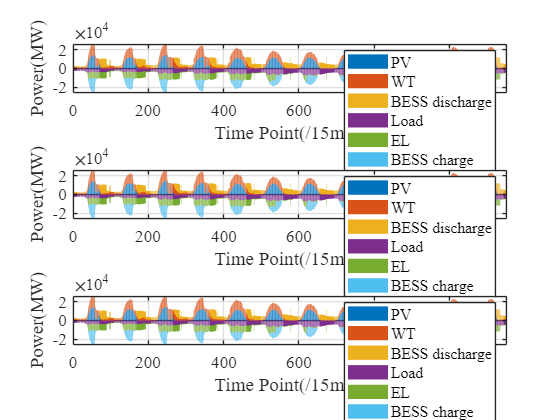

figure()
for i = 1:3
subplot(3,1,i)
bar([P_PV(:,i),P_WT(:,i),P_dis_bat(:,i)],'stacked');
hold on
bar(-[Power_load_reshape,Power_input_ALK(:,i),P_ch_bat(:,i)],'stacked');
legend('PV','WT','BESS discharge','Load','EL','BESS charge')
set(gca,'FontName','Times New Roman')
set(gca,'FontSize',13)
grid on
ylabel('Power(MW)')
xlabel('Time Point(/15min)')
end

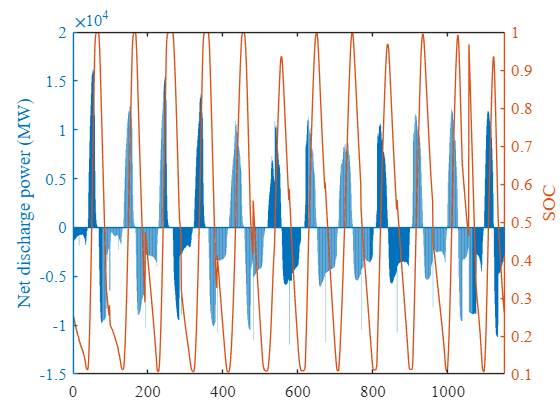

P_bat = P_ch_bat - P_dis_bat;
figure()
% for i = 1:N_S
subplot(1,1,1)
yyaxis left
bar(P_bat(:,1))
ylabel('Net discharge power (MW)')
yyaxis right
plot(E_bat(:,1)/CAP_bat);
index_bat = value(index_bat);
ylabel('SOC')
set(gca,'FontName','Times New Roman')
set(gca,'FontSize',13)

% end

sum(P_ch_bat.*P_dis_bat,'all')

ans = 8.3104e-06

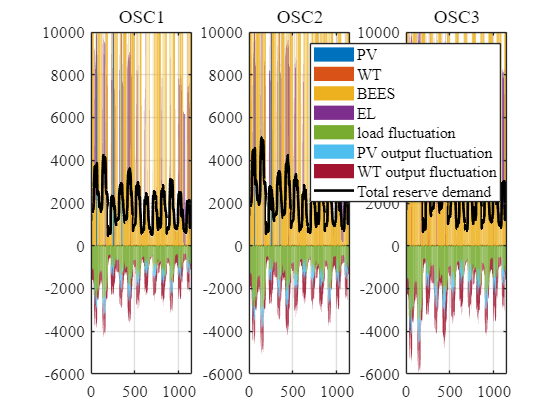

figure()
R_UP_PV = value(R_UP_PV);
R_UP_WT = value(R_UP_WT);
R_UP_bat = value(R_UP_bat);
R_UP_ALK = value(R_UP_ALK);
R_PV_req__ = value(R_PV_req__);
R_WT_req__ = value(R_WT_req__);
figure()
for i = 1:N_S
subplot(1,3,i)
bar([R_UP_PV(:,i),R_UP_WT(:,i),R_UP_bat(:,i),R_UP_ALK(:,i)],'stacked');
hold on
bar(-[R_load_up_req_(:,i),R_PV_req__(:,i),R_WT_req__(:,i)],'stacked');
hold on
plot(R_load_up_req_(:,i)+R_PV_req__(:,i)+R_WT_req__(:,i),'Color','black','LineWidth',2)
if i == N_S
legend('PV','WT','BEES','EL','load fluctuation','PV output fluctuation','WT output fluctuation','Total reserve demand')
end
set(gca,'FontName','Times New Roman')
set(gca,'FontSize',13)
name = ['OSC',int2str(i)];
title(name)
ylim([-6000,10000])
grid on
end

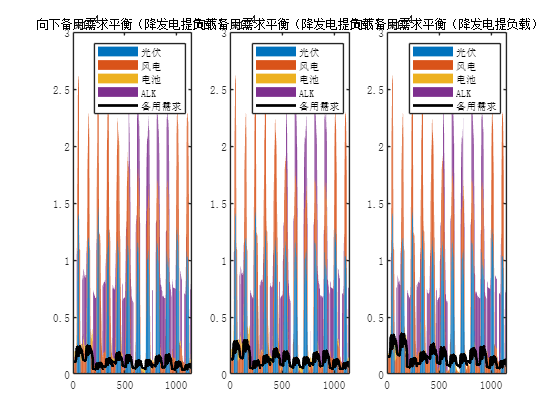

R_DOWN_PV = value(R_DOWN_PV);
R_DOWN_WT = value(R_DOWN_WT);
R_DOWN_bat = value(R_DOWN_bat);
R_DOWN_ALK = value(R_DOWN_ALK);
figure()
for i = 1:N_S
subplot(1,3,i)
bar([R_DOWN_PV(:,i),R_DOWN_WT(:,i),R_DOWN_bat(:,i),R_DOWN_ALK(:,i)],'stacked');
hold on
plot(R_load_down_req_(:,i),'Color','black','LineWidth',2)
legend('光伏','风电','电池','ALK','备用需求')
set(gca,'FontName','宋体')
title('向下备用需求平衡（降发电提负载）')
end

annal_total_kwh = sum(Power_load.*Day_num*t_min,'all')*10^3;
loce_total = (-NPV)/annal_total_kwh/25 %元/kwh

loce_total = 0.2901

FLT_PV = sum(P_PV_unit.*Day_num/4,'all')

FLT_PV = 1.7898e+03

FLT_WT = sum(P_WT_unit.*Day_num/4,'all')

FLT_WT = 2.4368e+03

cost_unit_WT_KW = cost_unit_WT/1000;
cost_unit_PV_KW = cost_unit_PV/1000;
loce_pv = cost_unit_PV_KW/(FLT_PV * 25); %元/kwh 
loce_wt = cost_unit_WT_KW/(FLT_WT * 25); %元/kwh 

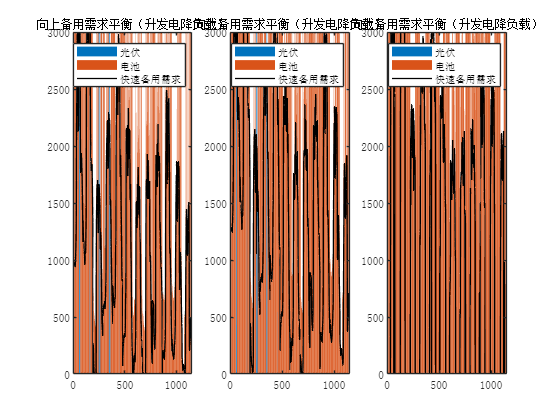

P_p_up_lim = value(P_p_up_lim);
P_f_up_lim = value(P_f_up_lim);
P_p_lim_up_real = max(P_p_up_lim,0);
P_f_lim_up_real = max(P_f_up_lim,0);
P_p_up = value(P_p_up);
P_f_up = value(P_f_up);
figure()
for i = 1:N_S
subplot(1,3,i)
bar([R_UP_PV(:,i),R_UP_bat(:,i)],'stacked');
hold on
plot(P_f_lim_up_real(:,i),'Color','black','LineWidth',1)
legend('光伏','电池','快速备用需求')
set(gca,'FontName','宋体')
title('向上备用需求平衡（升发电降负载）')
ylim([0,round(max(P_f_lim_up_real(:,i))/3000)*3000])
end

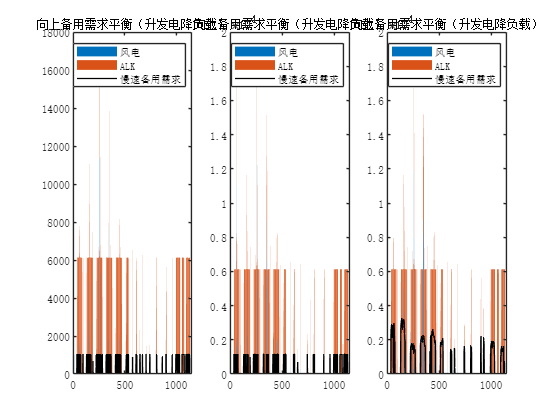

figure()
for i = 1:N_S
subplot(1,3,i)
bar([R_UP_WT(:,i),R_UP_ALK(:,i)],'stacked');
hold on
plot(P_p_lim_up_real(:,i),'Color','black','LineWidth',1)
legend('风电','ALK','慢速备用需求')
set(gca,'FontName','宋体')
title('向上备用需求平衡（升发电降负载）')
end

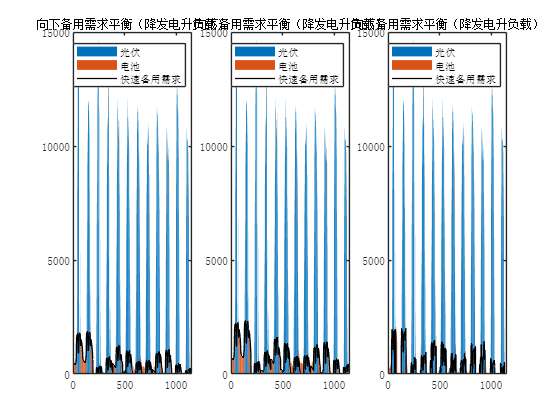

P_p_down_lim = value(P_p_down_lim);
P_f_down_lim = value(P_f_down_lim);
P_p_lim_down_real = max(P_p_down_lim,0);
P_f_lim_down_real = max(P_f_down_lim,0);
P_p_down = value(P_p_down);
P_f_down = value(P_f_down);
figure()
for i = 1:N_S
subplot(1,3,i)
bar([R_DOWN_PV(:,i),R_DOWN_bat(:,i)],'stacked');
hold on
plot(P_f_lim_down_real(:,i),'Color','black','LineWidth',1)
legend('光伏','电池','快速备用需求')
set(gca,'FontName','宋体')
title('向下备用需求平衡（降发电升负载）')
end

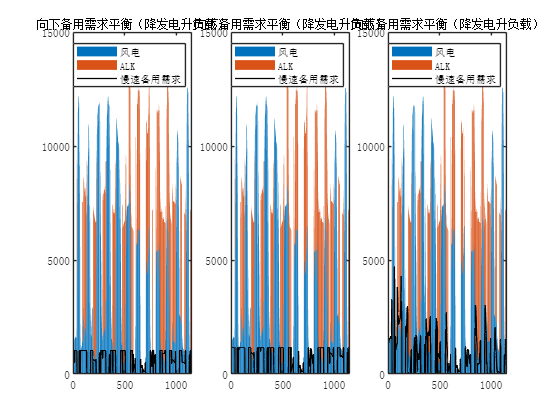

figure()
for i = 1:N_S
subplot(1,3,i)
bar([R_DOWN_WT(:,i),R_DOWN_ALK(:,i)],'stacked');
hold on
plot(P_p_lim_down_real(:,i),'Color','black','LineWidth',1)
legend('风电','ALK','慢速备用需求')
set(gca,'FontName','宋体')
title('向下备用需求平衡（降发电升负载）')
end

(CAP_PV+CAP_WT)*0.1

ans = 3.2662e+03

max(R_load_up_req_+R_PV_req_+R_WT_req_)

Nonlinear matrix variable 1x3 (full, real, 3 variables)
Values in range [4242.361,5998.621]
Coeffiecient range: 1 to 1


I_s = value(I_s);

core_result = [CAP_AKL,CAP_PV,CAP_WT,CAP_bat,NPV,loce_total];

save('result_base.mat', 'P_dis_bat','P_ch_bat','R_DOWN_PV','R_DOWN_WT','R_DOWN_bat','R_DOWN_ALK','R_load_down_req_',...
    'R_UP_PV','R_UP_WT','R_UP_bat','R_UP_ALK','R_load_up_req_','R_PV_req__','R_WT_req__','CAP_AKL','CAP_PV','CAP_WT',...
    'CAP_bat','Power_load_reshape','P_PV','P_WT','Power_input_ALK')